## Question 1


$$f_1(x,y) = -8x + 12y + x^2 -2x^4-2xy+4y^2$$


syms x y %declare symbolic variables
f1 = sym(-8*x+12*y+x^2-2*x^4-2*x*y+4*y^2) %define symbolic function

$$f1 = -2\,x^{4}+x^{2}-2\,x\,y-8\,x+4\,y^{2}+12\,y$$

f1 = matlabFunction(f1)

f1 = function_handle with value:
    @(x,y)x.*-8.0+y.*1.2e+1-x.*y.*2.0+x.^2-x.^4.*2.0+y.^2.*4.0


%create a function (gradAscent.m) to find optima 
% using Golden section method (golden.m)
[~,~,~, cache1] = gradAscent(-1,1,f1,0,0,0.001)

cache1 =          0         0         0
   -1.0832   -0.9923   -3.0330
   -1.0009   -0.9999   -2.9996
   -1.0002   -1.0001   -3.0005
   -1.0000   -0.9999   -2.9996


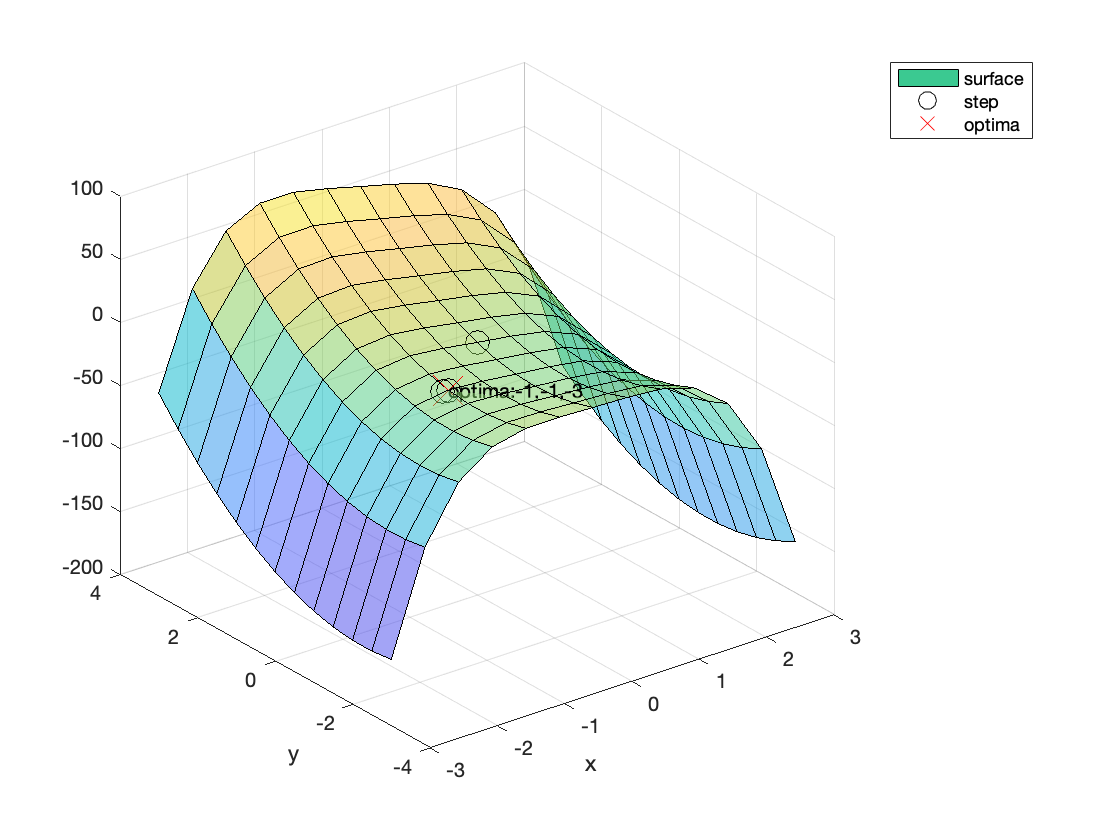

%plot 3d surface plot using (gradAscent_graph)
gradAscent_graph(-3,3,cache1,f1)


$$f_2(x,y) = 2x - x^2 - 2y^2 + 2xy$$


syms x y %declare symbolic variables
f2 = sym(2*x-x^2-2*y^2+2*x*y) %symbolic function

$$f2 = -x^{2}+2\,x\,y+2\,x-2\,y^{2}$$

f2 = matlabFunction(f2)

f2 = function_handle with value:
    @(x,y)x.*2.0+x.*y.*2.0-x.^2-y.^2.*2.0


[~,~,~, cache2] = gradAscent(0,1,f2,-1,1,0.001)

cache2 =    -1.0000    1.0000   -7.0000
    2.0002    0.9997    2.0000
    1.9995    1.0010    2.0000
    2.0010    1.0007    2.0000


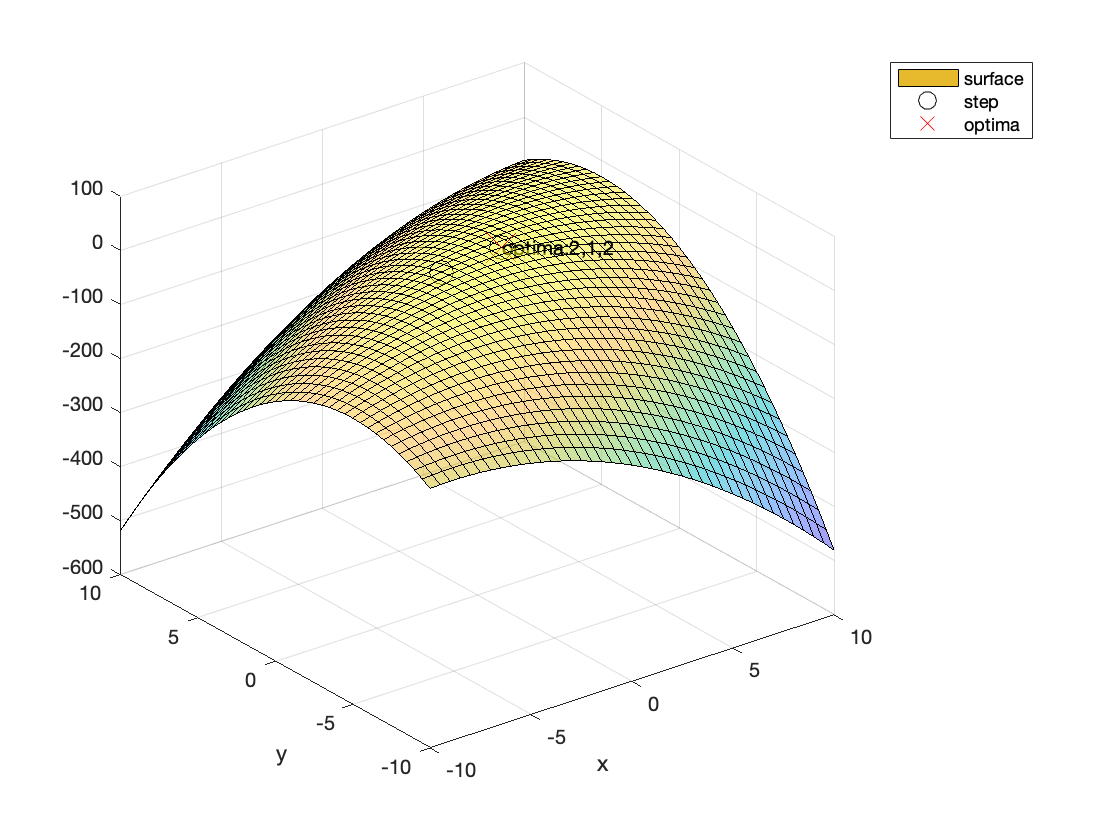

%plot 3d surface plot using (gradAscent_graph)
gradAscent_graph(-10,10,cache2,f2)


$$f_3(x,y) = -(x+y)\exp[-(x^2+y^2)]$$


syms x y %declare symbolic variables
f3 = sym(-(x+y)*exp(-(x^2+y^2))); 
f3 = matlabFunction(f3)

f3 = function_handle with value:
    @(x,y)-exp(-x.^2-y.^2).*(x+y)


[~,~,~, cache3] = gradAscent(-1,1,f3,0.5,0.5,0.001)

cache3 =     0.5000    0.5000   -0.6065


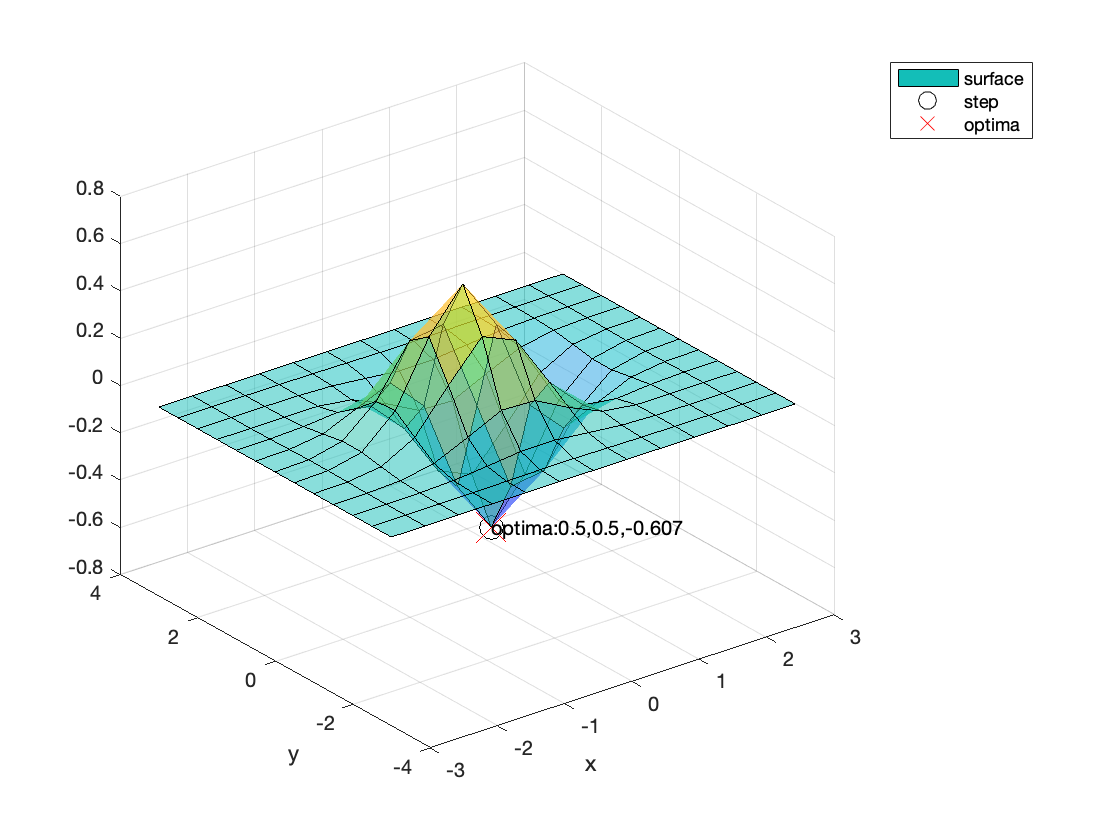

%plot 3d surface plot using (gradAscent_graph)
gradAscent_graph(-3,3,cache3,f3)


$$f_4(x,y) = y\sin(x) - x\cos(y)$$


syms x y %declare symbolic variables
f4 = sym(y.*sin(x) - x.*cos(y)); %sym(0.5*sqrt(160-4*x^2-y^2)) %sym(x^3 - 3*x*y^2) %symbolic function for monkey saddle
f4 = matlabFunction(f4)

f4 = function_handle with value:
    @(x,y)-x.*cos(y)+y.*sin(x)


[xmax,ymax,fmax, cache4] = gradAscent(-0.5,0.5,f4,2,-0.5,0.001)

xmax = -1.5717

ymax = -1.5703

fmax = 1.5711

cache4 =     2.0000   -0.5000   -2.2098
    1.6656   -0.4755   -1.9542
    1.2439   -0.3594   -1.5049
    0.7186   -0.6137   -0.9915
    0.0793   -0.7356   -0.1171
   -0.6577   -0.7481    0.9394
   -1.3197   -0.8297    1.6946
   -1.7600   -0.8318    2.0024
   -2.0181   -0.9906    1.9994
   -2.0775   -1.3349    1.6527


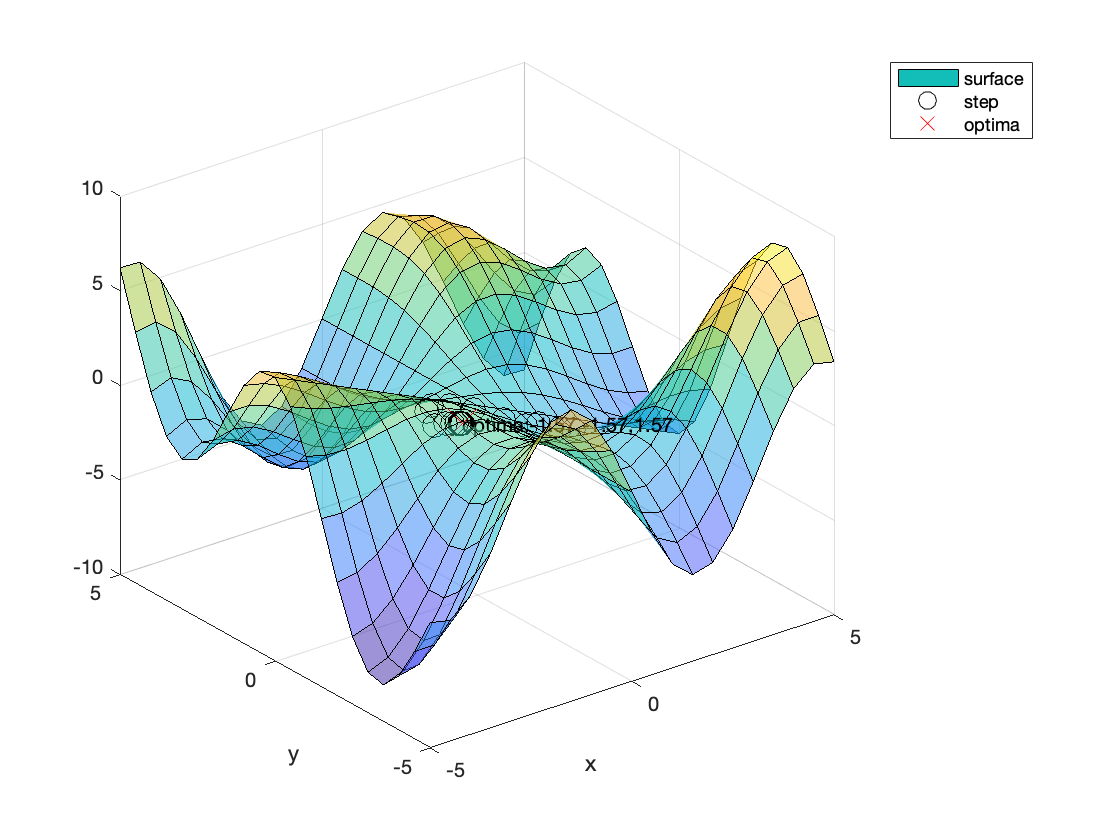

gradAscent_graph(-5,5,cache4,f4)

## Question 2

### Polynomial interpolation

sin_function = @(x)(sin(x));
%define all the data points, 5, 20, 50
five_points = linspace(0,2*pi,5);

twenty_points = linspace(0,2*pi,20);

fifty_points = linspace(0,2*pi,50);

%place the data points in a cell structure for reptitive tasks
data_points_x = {five_points,twenty_points, fifty_points};
data_points_y = cell(1,length(data_points_x));
for i = 1:length(data_points_x)
    data_points_y{1,i} = sin_function(data_points_x{i});
end

%create polyInterp.m function to compute polynomial interpolation
poly_coeff = cell(1,length(data_points_x));
for i = 1:length(data_points_x)
    poly_coeff{1,i} = polyInterp(data_points_x{i},data_points_y{i},4);
end

%original sin curve x and y values to plot the original sin curve
x = 0:pi/100:2*pi; %x values to make original sine curve
y = sin(x); %original sine y values

X = [x.^0;x.^1;x.^2;x.^3;x.^4]; %concat all x values from 0 to 4th power
y_poly = cell(1,length(data_points_x)); %fit polynomial lines for diff data size

for i = 1:length(data_points_x)
    y_poly{1,i} = poly_coeff{1,i}'*X;
end

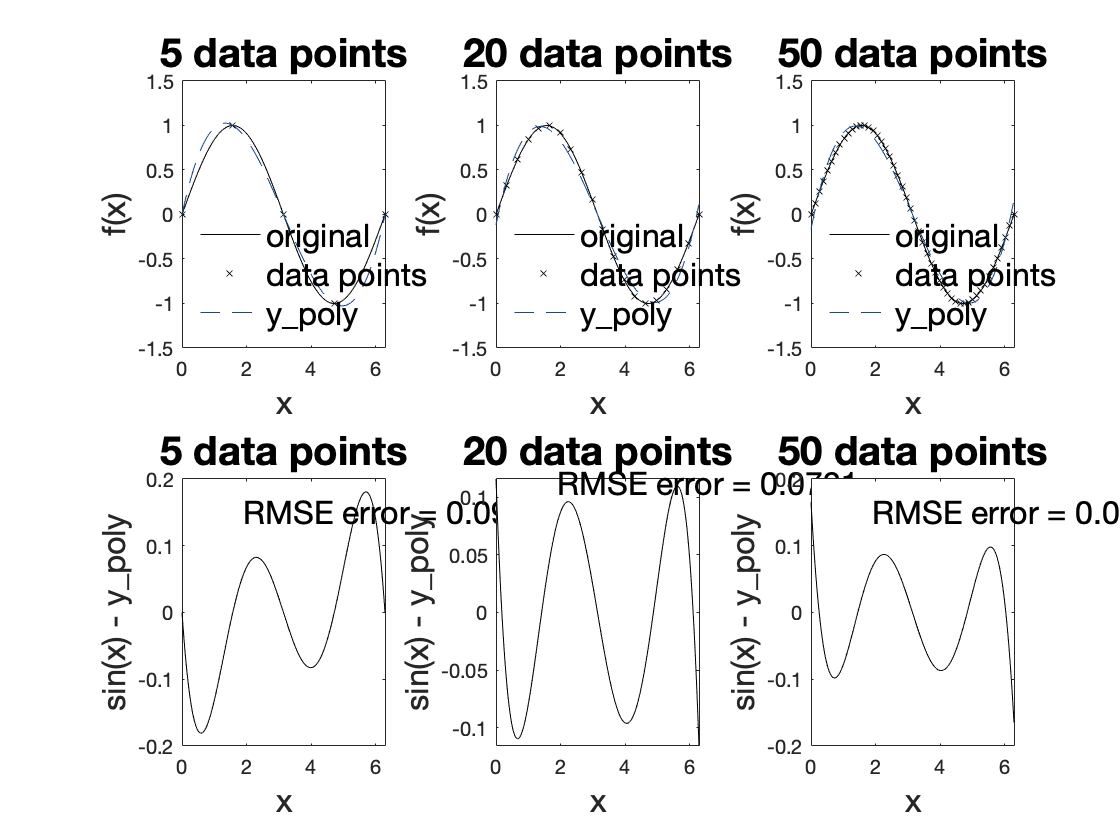

%create function (interpolating_graph.m) to plot graph. 
% generate random colours for interpolated curve
interpolating_graph(x,y,data_points_x,data_points_y,y_poly)

### Newton's interpolating polynomial

%create x coord tuples for each x data set and store in cell array
data_points_x_tuples = cell(1,length(data_points_x));

for i = 1:length(data_points_x_tuples)
    tuples = cell(1,length(data_points_x{1,i}));
    for j = 1:length(data_points_x{1,i})
        tuples{1,j} = [data_points_x{1,i}(j) data_points_x{1,i}(j)];
        data_points_x_tuples{1,i}{1,j} = tuples{1,j};
    end
end

data_points_x_tuples

data_points_x_tuples = 1×3 cell array
    {1×5 cell}    {1×20 cell}    {1×50 cell}


%create a cell array to store all newton's b coefficients for each data set
newton_B = cell(1,length(data_points_x));

for i = 1:length(data_points_x_tuples)
    newton_B{1,i} = newton(data_points_x_tuples{1,i},data_points_y{i});
end

newton_B

newton_B = 1×3 cell array
    {1×5 double}    {1×20 double}    {1×50 double}



y_newton = cell(1,length(data_points_x));
for i = 1:length(data_points_x)
    y_newton{1,i} = evaluate_newton(x,data_points_x{i},newton_B{1,i});
end

y_newton

y_newton = 1×3 cell array
    {1×201 double}    {1×201 double}    {1×201 double}


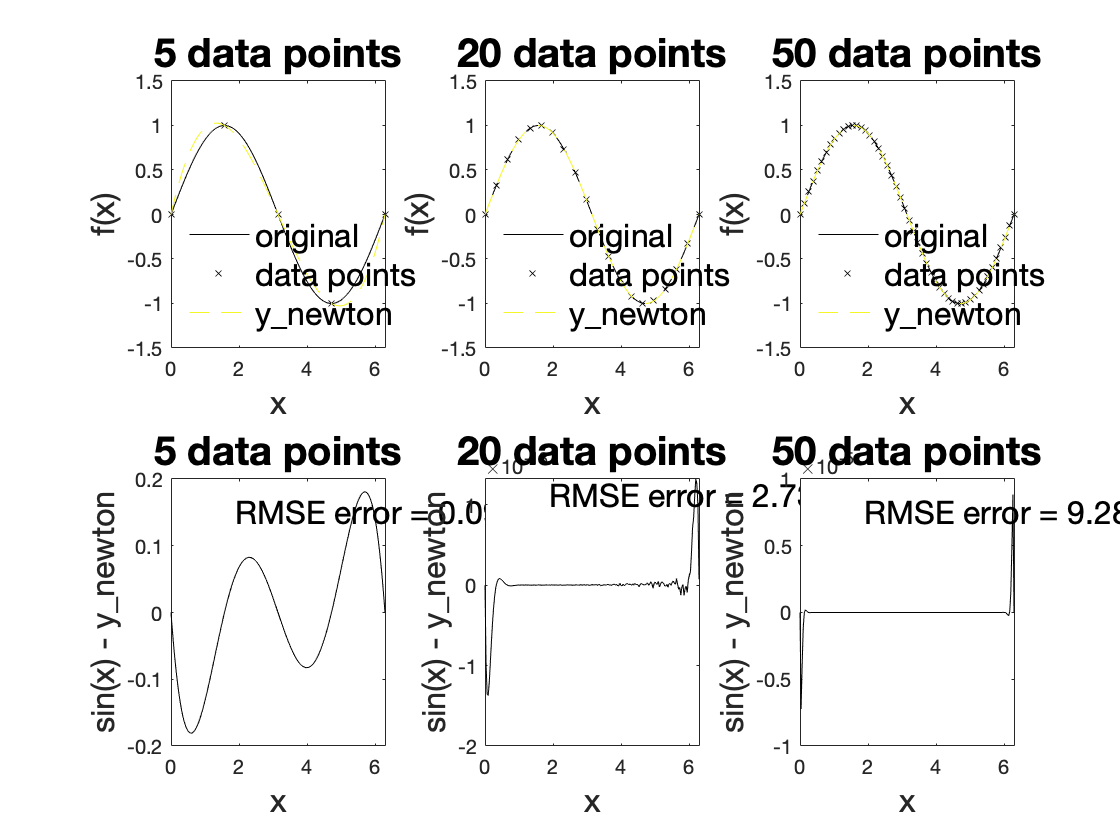

interpolating_graph(x,y,data_points_x,data_points_y,y_newton)

### Cubic spline interpolation

%compute the second derivation of interior points
second_deriv = cell(1,length(data_points_x));
for i = 1:length(data_points_x)
    second_deriv{1,i} = cubicSpline(data_points_x{i},data_points_y{i});
end

second_deriv

second_deriv = 1×3 cell array
    {5×1 double}    {20×1 double}    {50×1 double}



y_cubic = cell(1,length(data_points_x));
for i = 1:length(data_points_x)
    y_cubic{1,i} = eval_cubicSpline(second_deriv{1,i},data_points_x{i},data_points_y{i},x);
end

y_cubic

y_cubic = 1×3 cell array
    {1×201 double}    {1×201 double}    {1×201 double}


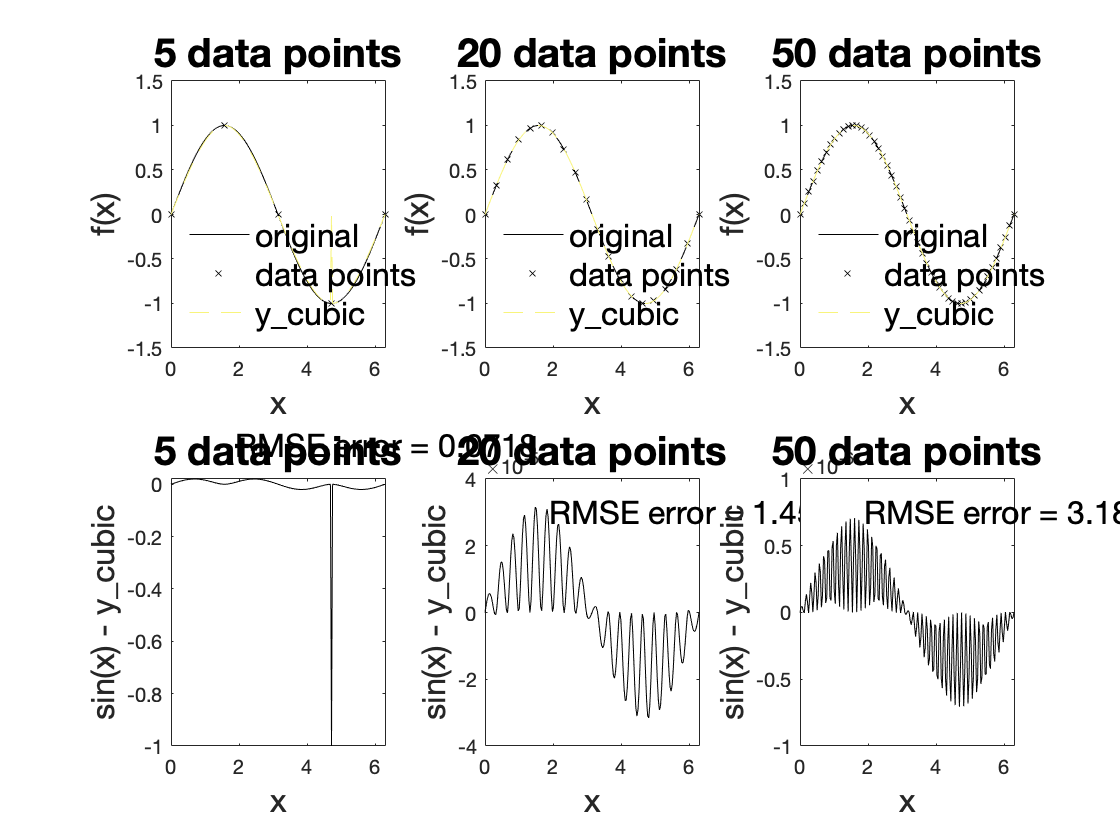

interpolating_graph(x,y,data_points_x,data_points_y,y_cubic)

### Investigating the effect of error magnitudes on fitted curves

rng('default') %set seed to ensure random number generated is the same
random_err = @(err)((2*err).*rand(1,length(data_points_y{1,2})) - err); %adjust only for 20 data points
err_bounds = [0.02, 0.1, 0.2]; %list of error bounds of 2%,10% and 20%
y_err = cell(1,length(err_bounds));
for i = 1:length(err_bounds)
    y_err{1,i} = data_points_y{1,2} + data_points_y{1,2}.*random_err(err_bounds(i));
end

y_err

y_err = 1×3 cell array
    {1×20 double}    {1×20 double}    {1×20 double}


#### Polynomial interpolation with varying error bounds

%create polyInterp.m function to compute polynomial interpolation
poly_coeff_err = cell(1,length(err_bounds));
for i = 1:length(err_bounds)
    poly_coeff_err{1,i} = polyInterp(data_points_x{2},y_err{1,i},4);
end

y_poly_err = cell(1,length(err_bounds)); %fit polynomial lines for diff data size

for i = 1:length(err_bounds)
    y_poly_err{1,i} = poly_coeff_err{1,i}'*X;
end

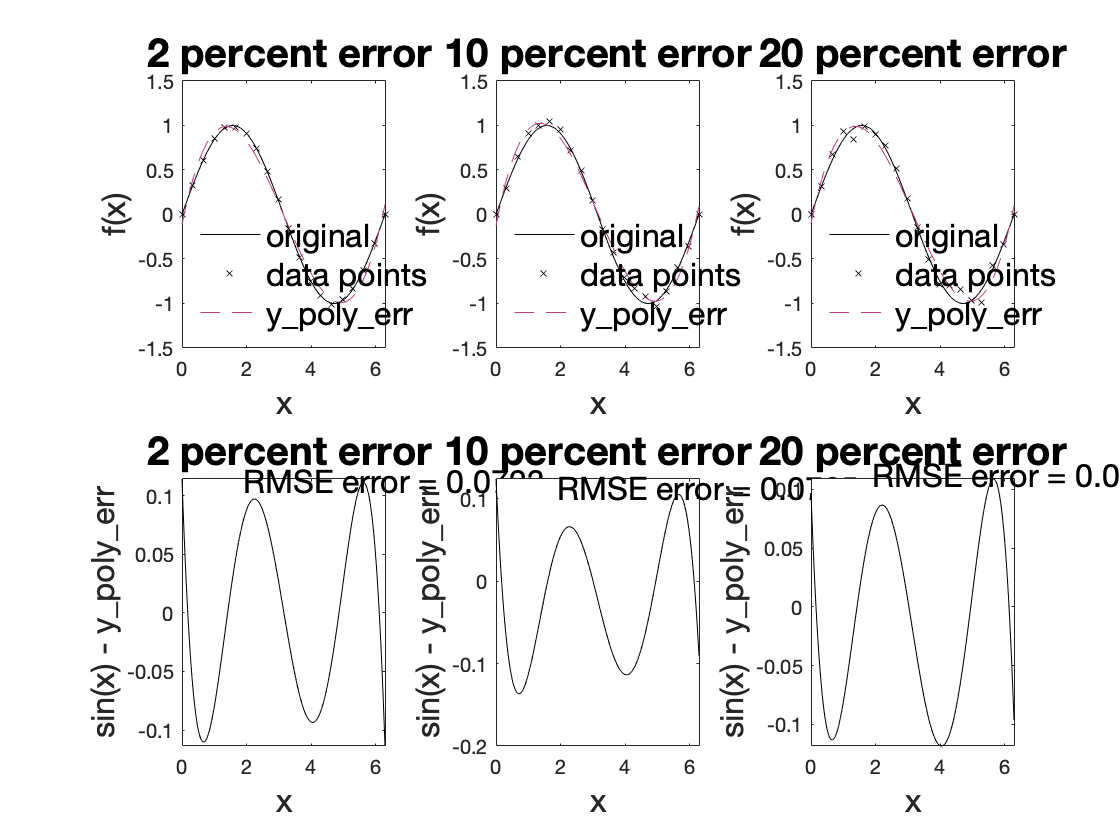

interpolating_err_graph(x,y,data_points_x,y_err,y_poly_err,err_bounds)

#### Newton interpolation with varying error bounds

%create a cell array to store all newton's b coefficients for each data set
newton_B_err = cell(1,length(err_bounds));

for i = 1:length(err_bounds)
    newton_B_err{1,i} = newton(data_points_x_tuples{1,2},y_err{1,i});
end

newton_B_err

newton_B_err = 1×3 cell array
    {1×20 double}    {1×20 double}    {1×20 double}



y_newton_err = cell(1,length(err_bounds));
for i = 1:length(err_bounds)
    y_newton_err{1,i} = evaluate_newton(x,data_points_x{2},newton_B_err{1,i});
end

y_newton_err

y_newton_err = 1×3 cell array
    {1×201 double}    {1×201 double}    {1×201 double}


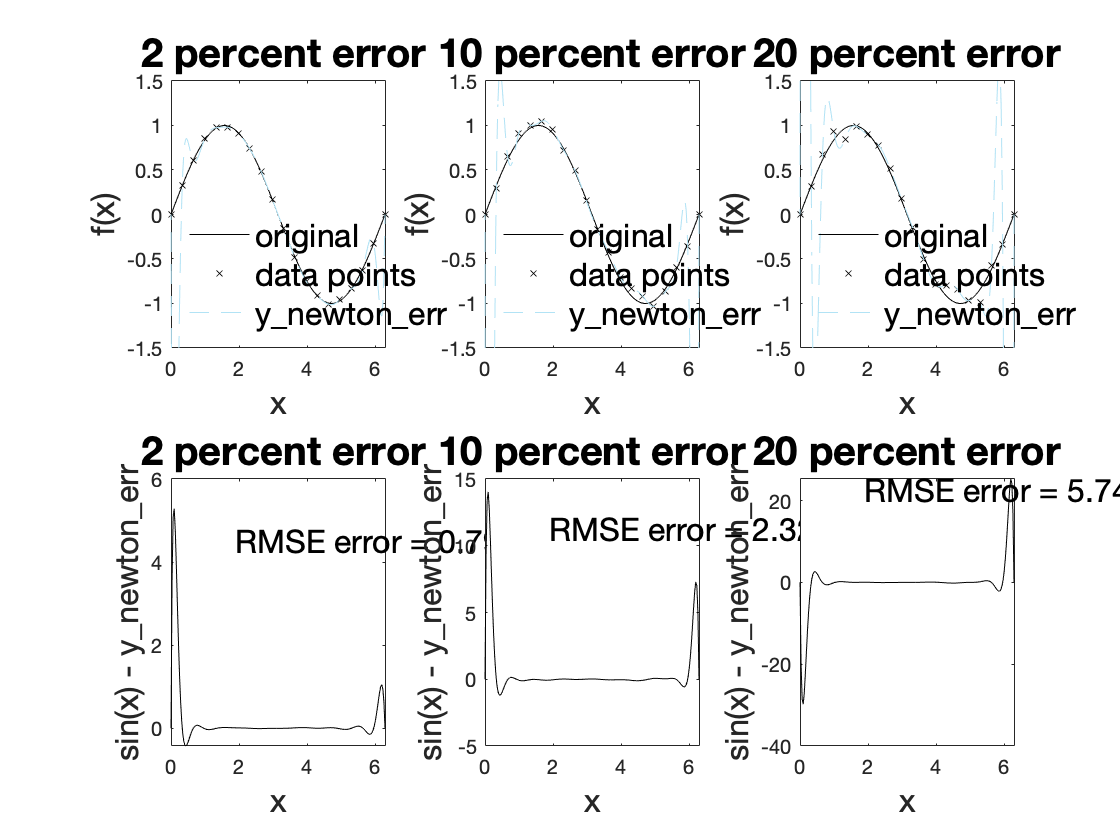

interpolating_err_graph(x,y,data_points_x,y_err,y_newton_err,err_bounds)

#### Cubic spline interpolation with varying error bounds

%compute the second derivation of interior points
second_deriv_err = cell(1,length(err_bounds));
for i = 1:length(err_bounds)
    second_deriv_err{1,i} = cubicSpline(data_points_x{2},y_err{1,i});
end

second_deriv_err

second_deriv_err = 1×3 cell array
    {20×1 double}    {20×1 double}    {20×1 double}



y_cubic_err = cell(1,length(err_bounds));
for i = 1:length(err_bounds)
    y_cubic_err{1,i} = eval_cubicSpline(second_deriv_err{1,i},data_points_x{2},y_err{1,i},x);
end

y_cubic_err

y_cubic_err = 1×3 cell array
    {1×201 double}    {1×201 double}    {1×201 double}


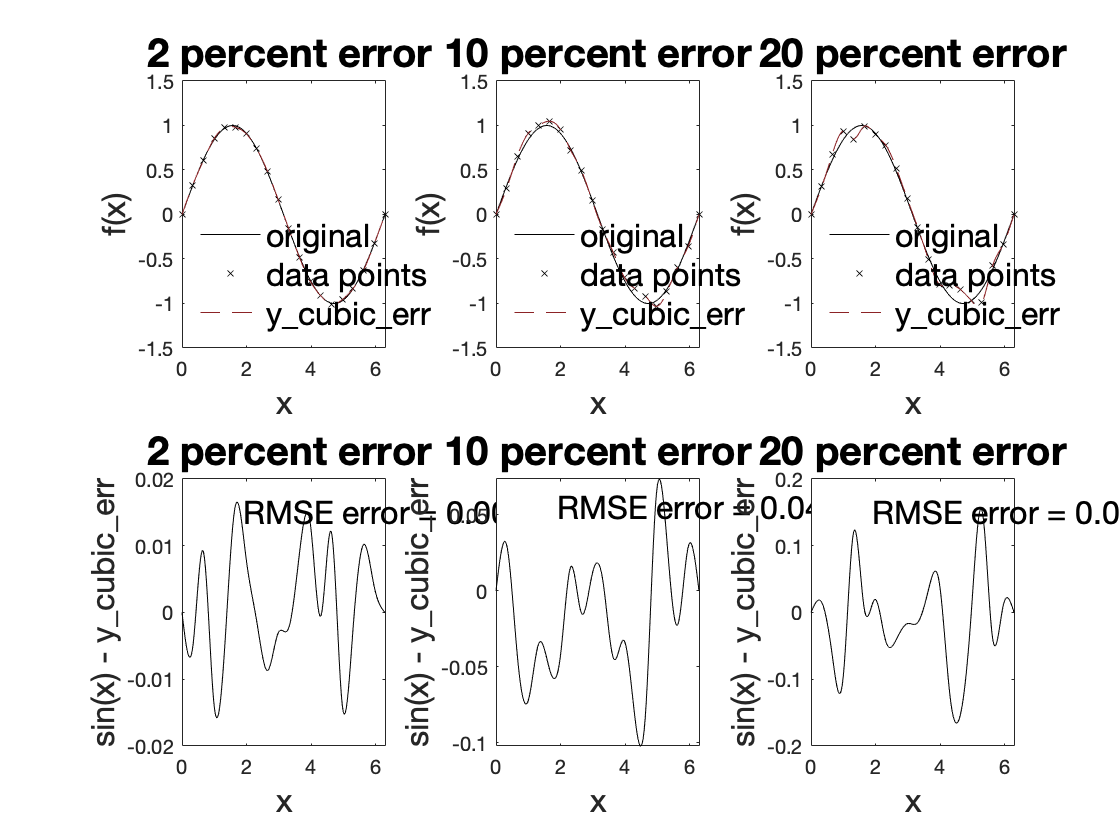

interpolating_err_graph(x,y,data_points_x,y_err,y_cubic_err,err_bounds)